load examgrades

x = grades(:,1);

[mu,sigma,muCI,sigmaCI] = normfit(x)

mu = 75.0083

sigma = 8.7202

muCI =    73.4321
   76.5846


sigmaCI =     7.7391
    9.9884


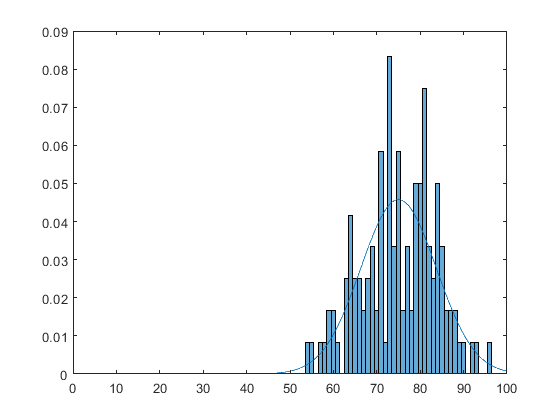

x_pdf = [1:0.1:100];
y = normpdf(x_pdf,mu,sigma);
 
figure
histogram(x,'Normalization','pdf')
line(x_pdf,y)

A = norminv(0.9,mu,sigma)

A = 86.1837

save('myparameter.mat','mu','sigma')